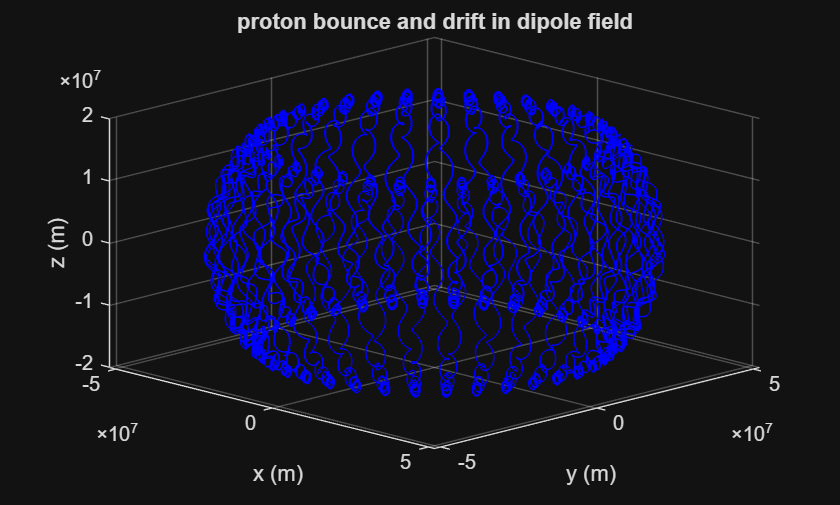

% representing the dipole magnetic field 

% define physical constants
q = 1.6e-19; % charge of proton in coulombs
m = 1.673e-27; % mass of proton in kg
re = 6371000; % Earth's radius in m
b0 = 31000e-9 * re^3; % dipole moment constant
v0 = 7500000; % new speed m/s

%% the dipole field strength at any distance r from Earth's center is b = b0 / r^3
b_at_start = b0 / (8*re)^3;

omega = (q * b_at_start) / m; % gyrofrequency equation, shows how fast the proton spins

t_gyro = (2 * pi) / omega; % calculate period of one full gyration/circle

dt = t_gyro / 5000; % time step between each step of RK4 integrator 
%% updated to 5000

n = 5000 * 1000; % number of time steps simulation will run for (5000 full circles worth of time, 1000 steps per circle)

t = zeros(1, n+1); % creates a row of n + 1 zeros in a row, time axis of simulation
x = zeros(1, n+1); % same thing but store the x position of the proton at every moment in time 
y = zeros(1, n+1); % same but y position
z = zeros(1, n+1); % same but z position
vx = zeros(1, n+1); % stores x component of proton's velocity at every moment
vy = zeros(1, n+1); % same but y component
vz = zeros(1, n+1); % same but z component

% set initial conditions
x(1) = 8 * re; % initial x position
y(1) = 0; % initial y position
z(1) = 0; % initial z position
vx(1) = v0; % initial x velocity
vy(1) = 0; % initial y velocity
vz(1) = v0; % initial z velocity


% RK4 time loop

for i = 1:n
    state = [x(i); y(i); z(i); vx(i); vy(i); vz(i)]; % state vector
    k1 = dt * lorentz(state, q, m, b0); % estimated change in all six quantities in one full time step 
    k2 = dt * lorentz(state + 0.5*k1, q, m, b0); % add half of the estimated change
    k3 = dt * lorentz(state + 0.5*k2, q, m, b0); % add half of the second estimated change
    k4 = dt * lorentz(state + k3, q, m, b0); % estimate change using the full third step
    new_state = state + (1/6) * (k1 + 2*k2 + 2*k3 + k4); % complete updated position and velo one time step later
    % new state = state + 1/6(k1 + 2k2 + 2k3 + k4) from Simpson's rule 

    x(i+1) = new_state(1); % take 1st value out of new_state and store in slot i+1 of the x array
    y(i+1) = new_state(2); % take 2nd value (y) " "
    z(i+1) = new_state(3); 
    vx(i+1) = new_state(4);
    vy(i+1) = new_state(5);
    vz(i+1) = new_state(6);
    t(i+1) = t(i) + dt; % takes current time stored in slot i and adds one dt to it
end

% plot results


figure;


plot3(x, y, z, 'b-');
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
title('proton bounce and drift in dipole field');
grid on;
view(45, 25);

showing the magnetic field lines

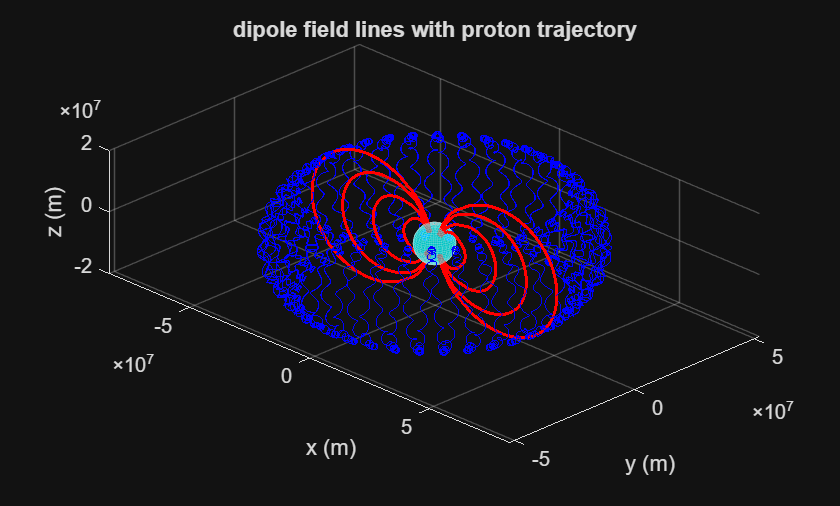

[X, Y, Z] = meshgrid(linspace(-15*re, 15*re, 30), ...
    linspace(-15*re, 15*re, 30), ...
    linspace(-15*re, 15*re, 30));
% creates 1d array of 30 evenly spaced numbers from -15 earth radii to 15
% earth radii. defining how far out in space the field lines are
% meshgrid- take the 3 lists of 30 numbers (one for each axis) and makes a full 3d grid where every
% x,y,z has it's own slot. the dots continue the code in a different line

% here we are using uppercase letters:

%(change these as the code updates)
% X: a 30x30x30 array (27000 numbers)
% Y: a 30x30x30 array (27000 numbers)
% Z: a 30x30x30 array (27000 numbers)
% vs
% x = state(1);   one single number
% y = state(2);   one single number
% z = state(3);   one single number

R = sqrt(X.^2 + Y.^2 + Z.^2);
% for every one of the 27000, computes distance from earth's center. the dot here 
% is critical, it means square every number in the array individually, without, it would try to square the whole matrix
% R is how far each grid point is from earth. the dipole strength depends
% entirely on this, falling off as 1/r^5 --->

Bx = b0 .* (3.*X.*Z) ./ R.^5;
By = b0 .* (3.*Y.*Z) ./ R.^5;
Bz = b0 .* (3.*Z.^2 - R.^2) ./ R.^5;

% Find where points are inside the Earth and zero them out.
% This stops streamlines from hitting the center singularity and shooting straight up
inside_earth = R < re;
Bx(inside_earth) = 0;
By(inside_earth) = 0;
Bz(inside_earth) = 0;

% computes all 3 components of the mag field vector at every point
% same as the one for lorentz force, but now applied to all 27000 points at
% once using array math


seeds_x = [2 4 6 8 -2 -4 -6 -8] * re;
seeds_y = zeros(1, 8);
seeds_z = zeros(1, 8);

% defines 8 starting points for field lines. seeds_x is a list of 8 x
% positions (2,4,6,8 earth radii on each side). seeds y and z are just row
% of 8 zeros, meaning all seeds start at y and z=0. 



figure;
% draw field lines starting at seeds; returns handle h1
% the last argument [0.1, 10000] are integration control options for streamline:
%  - first element is the step size used by the integrator (how far along the field
%    to advance between evaluations). smaller values give smoother/more accurate
%    streamlines but take longer to compute.
%  - second element is the maximum integration distance (total arc-length) the
%    streamline is allowed to grow. It stops the streamline once that length is reached.
h1 = streamline(X, Y, Z, Bx, By, Bz, seeds_x, seeds_y, seeds_z, [0.1, 10000]);
h2 = streamline(X, Y, Z, -Bx, -By, -Bz, seeds_x, seeds_y, seeds_z, [0.1, 10000]);

% this opens a new figure window and draws the streamlines (magnetic field lines).
% field lines are curves that are always tangent to the local B vector

set(h1, 'Color', 'r', 'LineWidth', 1.5);
set(h2, 'Color', 'r', 'LineWidth', 1.5);
hold on;





% h is a handle/reference to all the streamlines just drawn. we make the
% lines visible but not dominant, so thin
 

[sx, sy, sz] = sphere(30);
surf(sx*re, sy*re, sz*re, 'FaceColor', 'cyan', 'EdgeAlpha', 0.2, 'FaceAlpha', 0.5);

% (i just looked this up) puts earth at the center of the graph 
% surf draws the 3d surface 

xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
title('dipole field lines with proton trajectory');

plot3(x, y, z, 'b-');
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');



axis equal;

grid on;
view(45, 25);
% Enable interactive 3D rotation with mouse
rotate3d on;



function dstate = lorentz(state, q, m, b0) % dstate = [dx/dt, dy/dt, dz/dt, dvx/dt, dvy/dt, dvz/dt]
    dstate = zeros(6,1); % output variable to fill w/ derivatives


%% we extract x, y, z from the state vector because the magnetic field is no longer uniform and the field strength and direction now depend on position
    x = state(1);
    y = state(2);
    z = state(3);
    vx = state(4);
    vy = state(5);
    vz = state(6);


    r = sqrt(x^2 + y^2 + z^2);

%% equations for magnetic field of origin centered dipole in cartesian

    bx = b0 * (3*x*z) / r^5;
    by = b0 * (3*y*z) / r^5;
    bz = b0 * (3*z^2 - r^2) / r^5;

    dstate(1) = vx;
    dstate(2) = vy;
    dstate(3) = vz;
    dstate(4) = (q/m) * (vy*bz - vz*by);
    dstate(5) = (q/m) * (vz*bx - vx*bz);
    dstate(6) = (q/m) * (vx*by - vy*bx);

end